clear;
clc;

csvfile = csvread('test_data/data.csv');

odom = Odometry();

pose_backlog = [];

profile on;
for i=1:size(csvfile,1)
    time = csvfile(i,1);
    taco = csvfile(i,2);
    steer = csvfile(i,3);
    steerangle = Arduino_ROS.servo_to_steer_angle(steer);
    odom.update(taco, steerangle);
    pose = odom.odom_pose;
    pose_backlog = [pose_backlog ; time pose.translation.val_x pose.translation.val_y pose.rotation.value_radians];
end
profile off;
profile viewer;

plot(pose_backlog(:,2),pose_backlog(:,3));

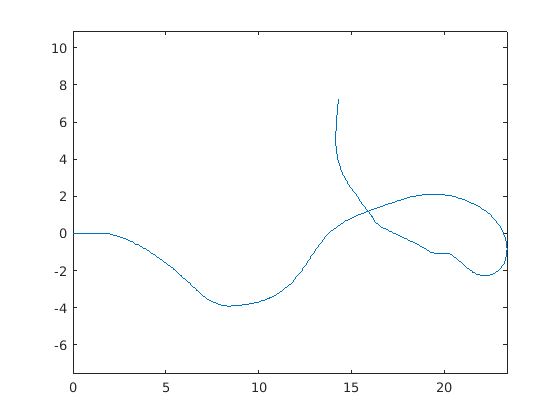

axis equal;